# Assignment #1

Connor Cavarretta

ECE 651

09/14/2025

## Question 2.5

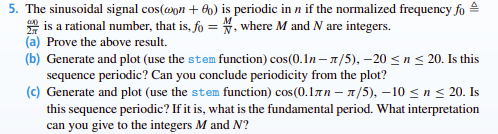

### a) 

A function $x(t)$ is periodic if $x(t) = x(t+T)$ $\forall \ t$

For the signal $cos(\omega_0n+\theta_0)$ to be periodic, the argument of the cosine must be off by $\pm 2\pi$one time period later. Neglecting $\theta_0$, the argument is:

 
$$2\pi\frac{M}{N}n$$


The time period $N_0$ can be defined as the inverse of $f_0$ which here is $\frac{N}{M}$. Replacing $n
$ with $(n+N_0)$, we get:


$$2\pi\frac{M}{N}(n+N_0) = 2\pi\frac{M}{N}\left(n+\frac{N}{M}\right) ... \\

= \ 2\pi\frac{M}{N}n + 2\pi$$


An irrational number does not have this relationship, therefore the normalized frequency must be rational.

### b)

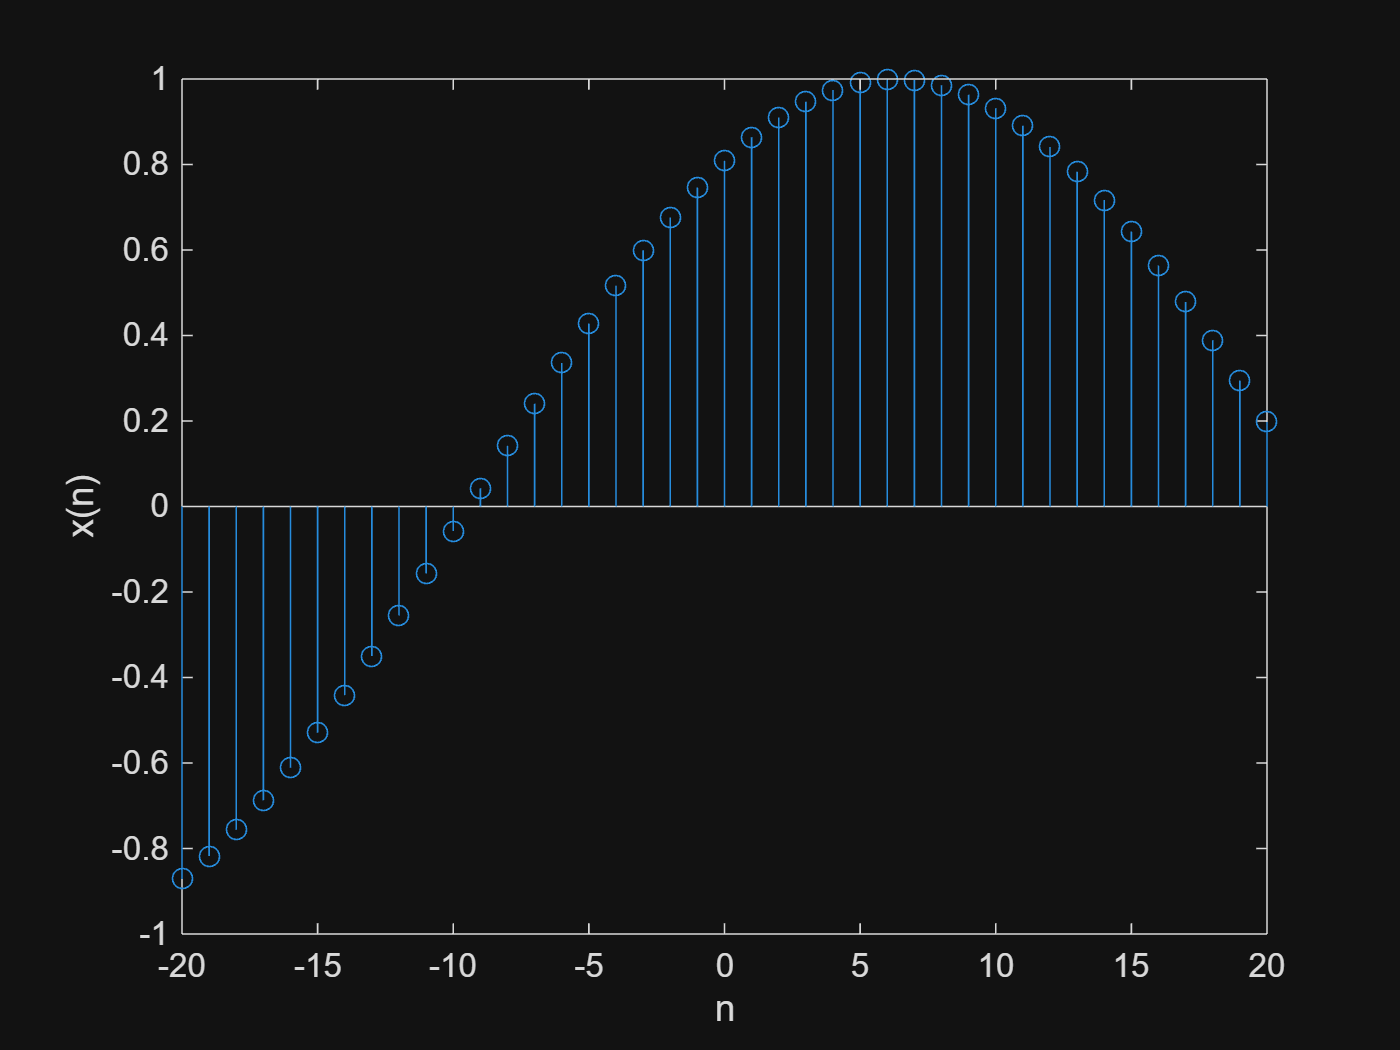

n   = -20:20;
x_n = cos(0.1*n - pi/5);
stem(n, x_n)
xlabel('n');
ylabel('x(n)');

This sequence is **NOT** periodic. We can conclude that this signal is not periodic by considering $\omega_0$:


$$\omega_0 = 0.1 \\
2\pi f_0 = 0.1 \\
f_0 = \frac{0.1}{2\pi}

\text{, Not Rational$$


However, we are not able to conclude from the graph alone due to the chart not capturing the entire period.

### c)

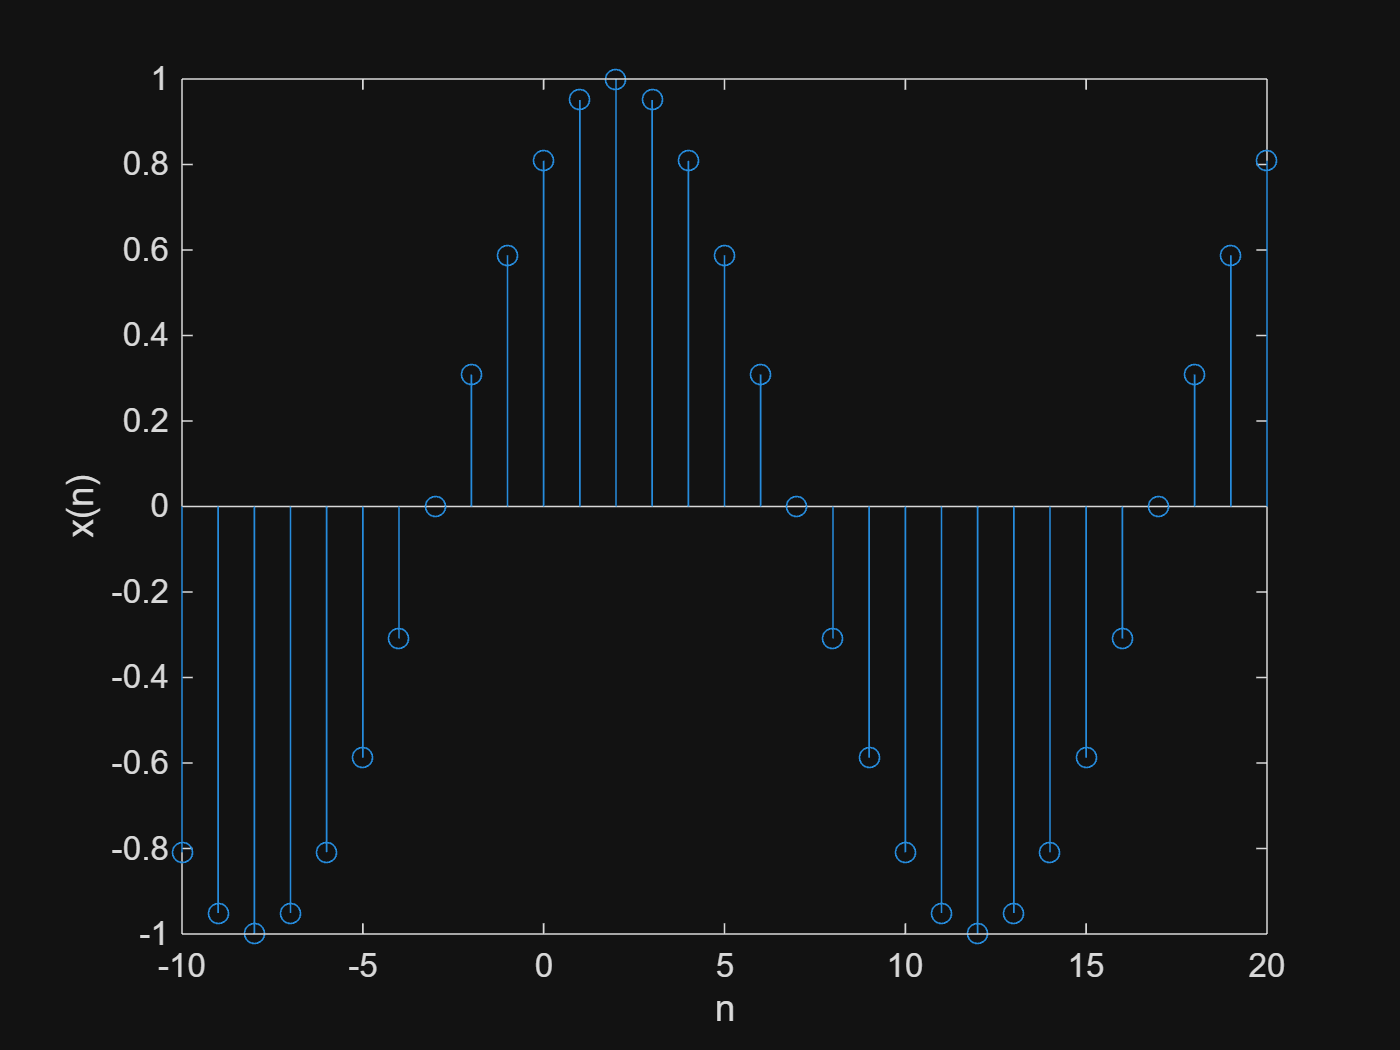

n   = -10:20;
x_n = cos(0.1*pi*n-pi/5);
stem(n, x_n);
xlabel('n')
ylabel('x(n)');

This sequence **IS** periodic and the fundamental period is 20. We can determine this by considering $\omega_0$:


$$\omega_0 = 0.1\pi\\
2\pi f_0 = 0.1\pi \\
f_0 = \frac{0.1}{2}
\rightarrow \frac{1}{20}\text{, Rational} \\
N_0  = \frac{1}{f_0} = 20$$


## Question 2.6

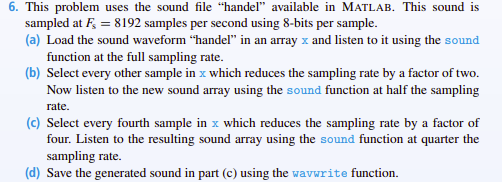

### a)

Load file and play sound.

x = load("handel.mat"); 
%sound(x.y, x.Fs)

### b)

Reduce the sample by a factor of two.

y_halfsample  = x.y(1:2:end);
Fs_halfsample = x.Fs / 2; 
%sound(y_halfsample, Fs_halfsample)

### c)

Reduce the sample by factor of four.

y_quartersample = x.y(1:4:end);
Fs_quartersample = x.Fs / 4; 
%sound(y_quartersample, Fs_quartersample);

### d)

Save the audio file.

% wavwrite has been deprecated, using MATLAB available function instead
%audiowrite("handel_quarter_sample.flac", y_quartersample, Fs_quartersample)

## Question 2.11

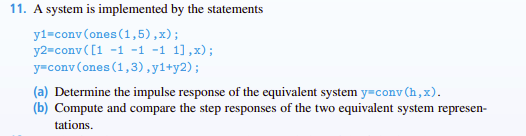

## Question 2.19

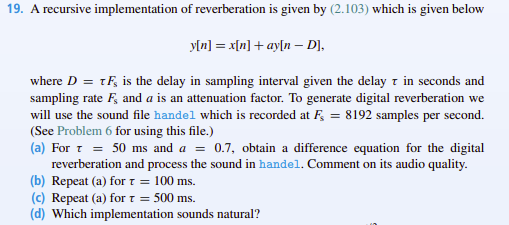

## Question 2.25

### b)

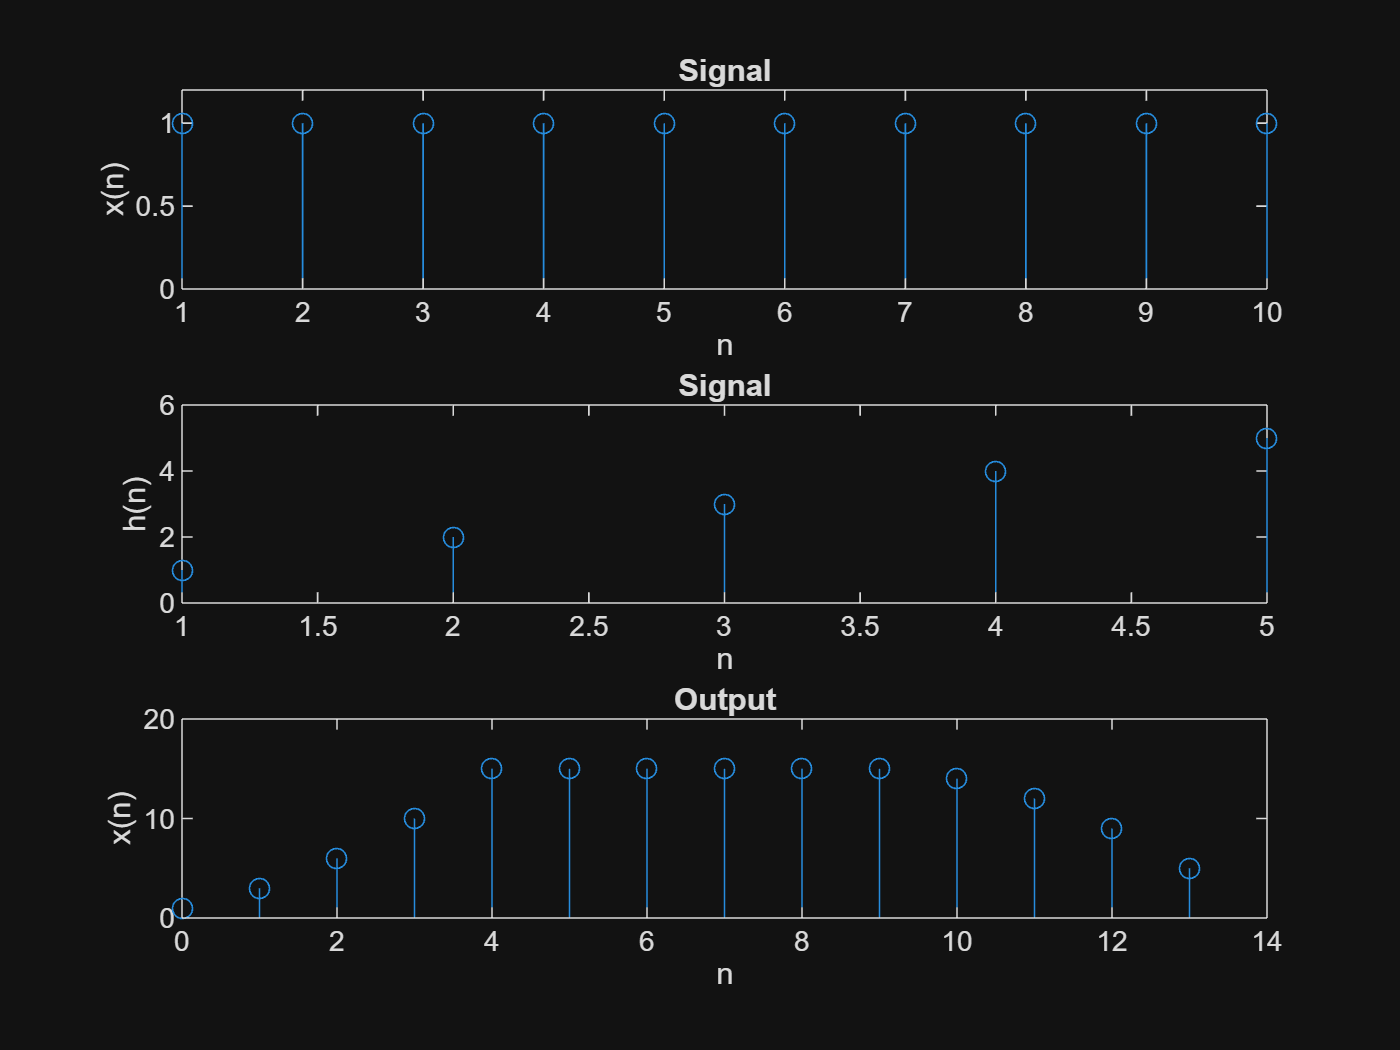

N = 10; M = 5;
x = ones([1,N]);
h = 1:M;
y = conv(h,x);

% Plot the convolution result
n_conv = 0:length(y)-1; 
figure;

% Signal plot
subplot(3,1,1)
stem(x);
ylim([0,1.2]);
xlabel('n');
ylabel('x(n)');
title('Signal');

% impulse response plot
subplot(3,1,2)
stem(h);
xlabel('n');
ylabel('h(n)');
title('Signal');

% Signal plot
subplot(3,1,3)
stem(n_conv, y);
ylim([0,20]);
xlabel('n');
ylabel('x(n)');
title('Output');

## Question 2.28

## Question 2.34

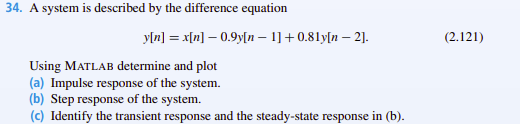

An effecient method of determing the impulse and step response using matlab is to identify the transfer function of the system in the z-domain:


$$y[n] = x[n] - 0.9y[n-1] + 0.81y[n-2] \\
y[n] + 0.9y[n-1] - 0.81y[n-2] = x[n] \\
\left(1 + 0.9z^{-1} - 0.81z^{-2}\right)Y(z) = X(z) \\
\frac{Y(z)}{X(z)} = \frac{1}{1 + 0.9z^{-1} - 0.81z^{-2}} $$


The system can now be designed in matlab by using the coeffecients of the transfer function.

## a)

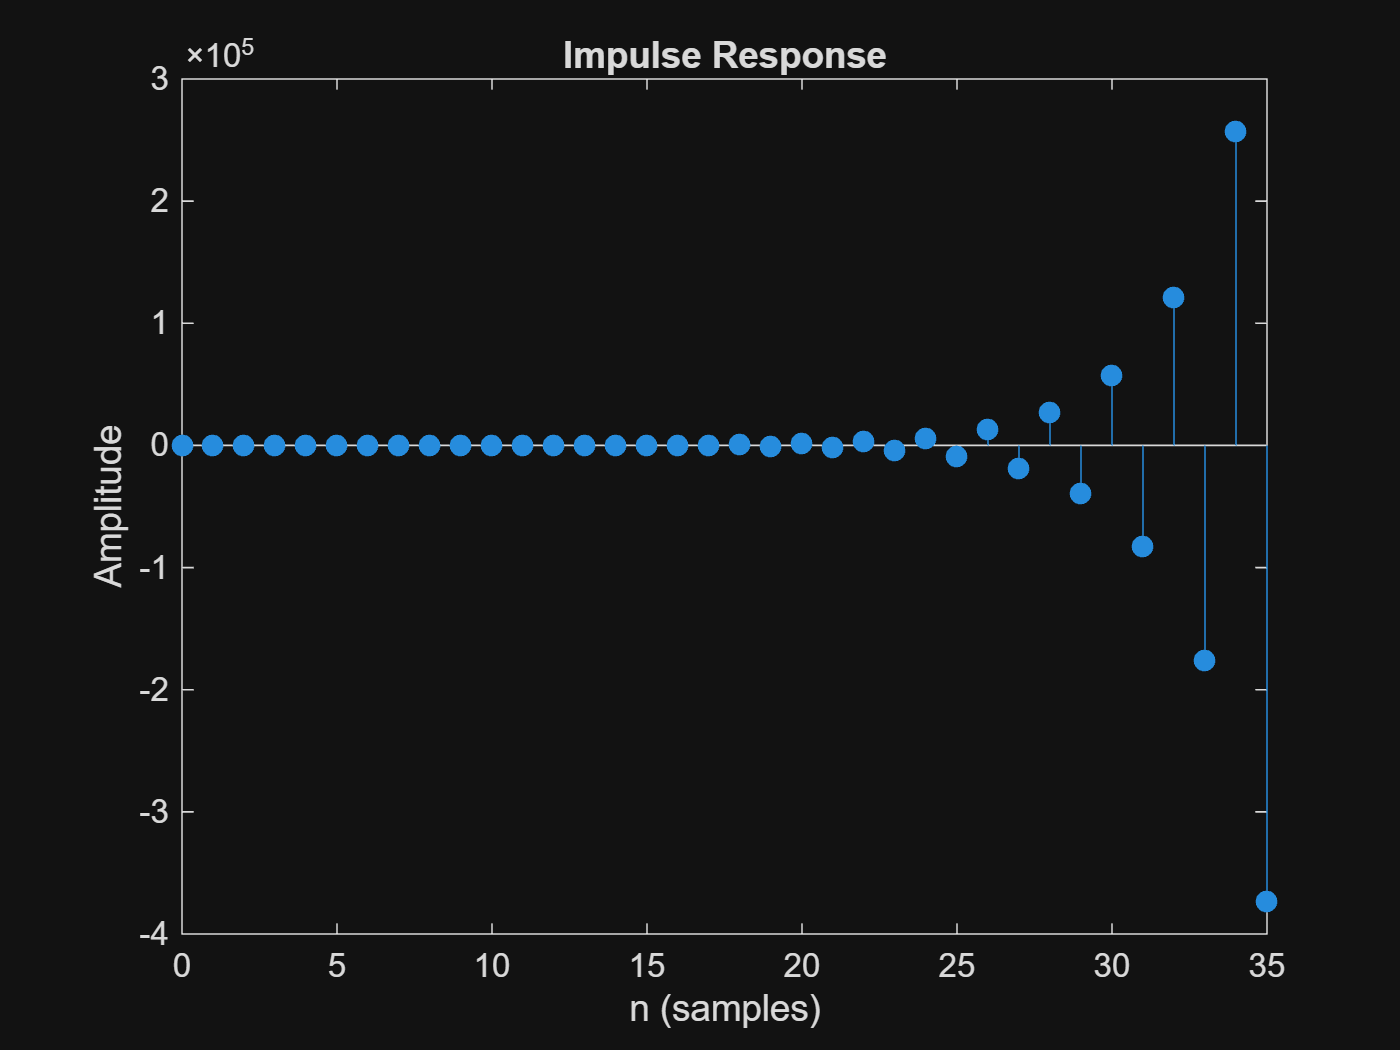

% Define system
b = 1;               % numerator coeffecients
a = [1, 0.9, -0.81]; % denominator coeffecients 

% Impulse Response
figure;
impz(b,a)

## b)

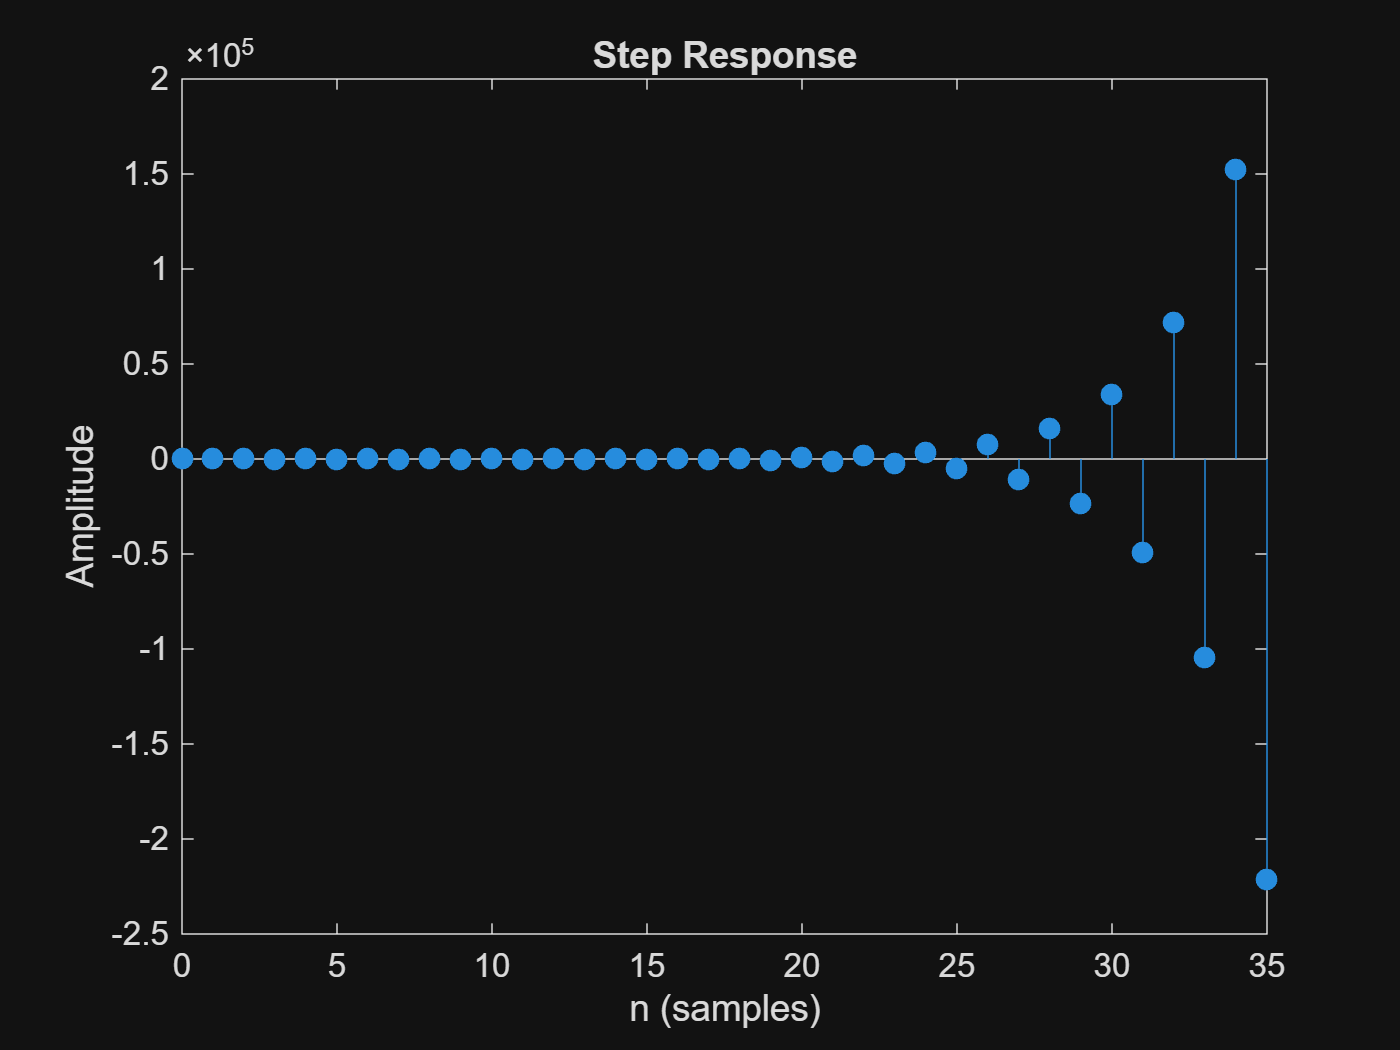

% Step response
figure;
stepz(b,a)

## c)

The system defined is unstable, therefore the entire response is transient and there is no steady state. 

## Question 2.41

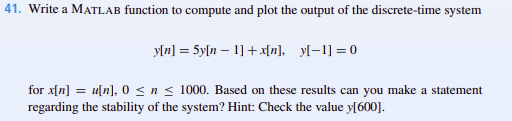

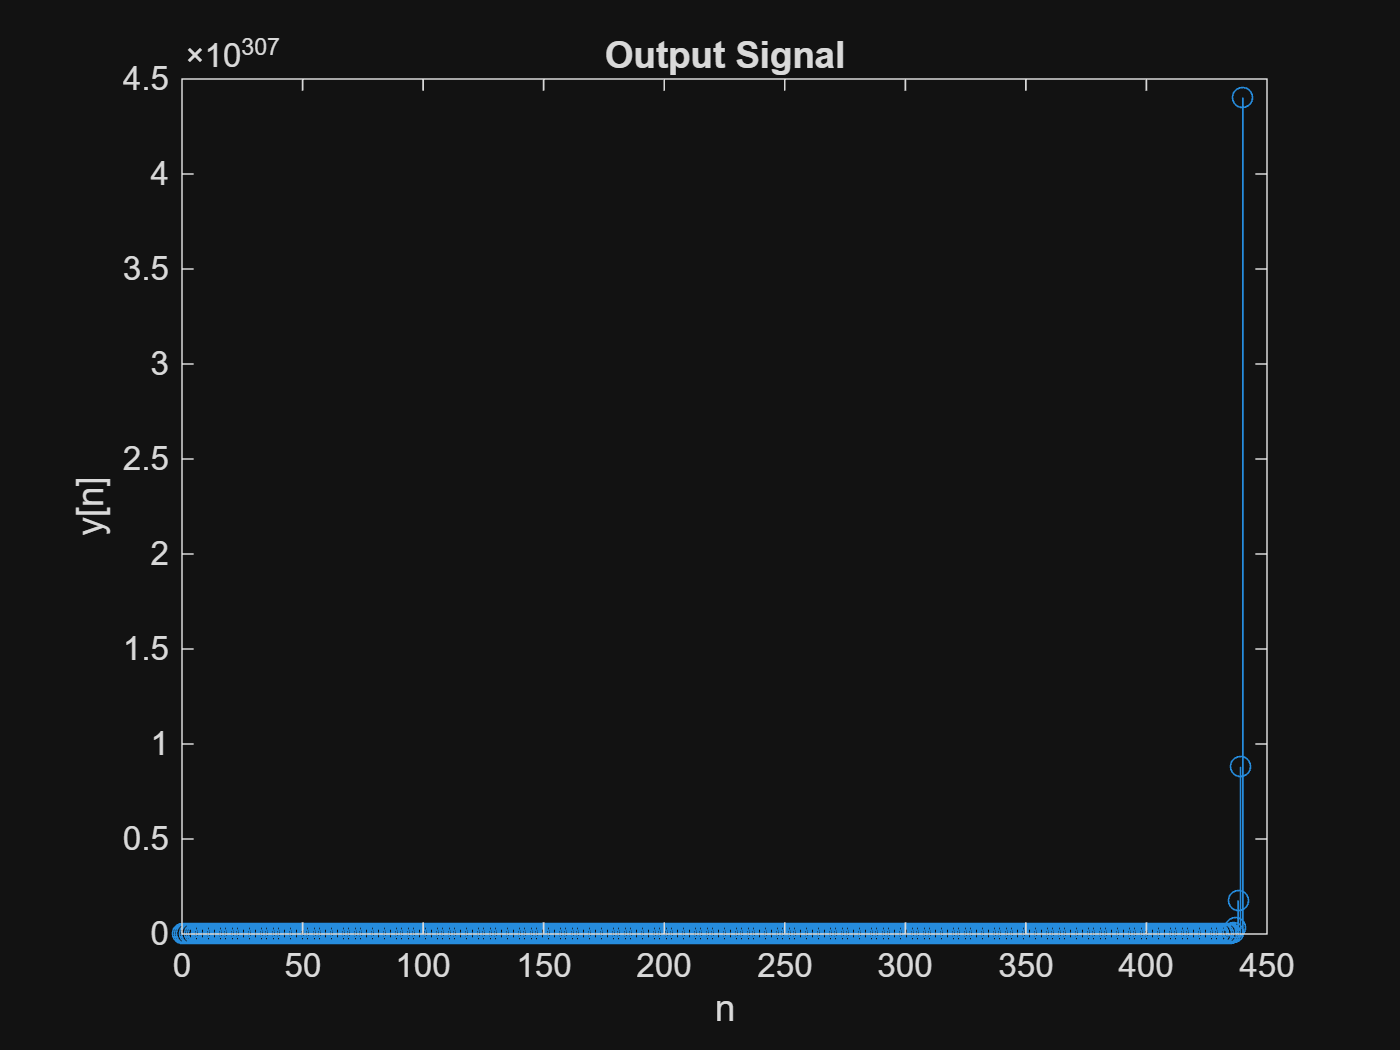

%% Using recursion to solve
n = 0:1e3;

% Input signal
x = ones([1,length(n)]); % x[n] = u[n]

% Set up output signal
y = zeros([1,length(n)]);

% Initial condition
y_0  = 0;
y(1) = 5*y_0 + x(1);

% recursively solve system
for i=2:length(n)
   y(i) = 5*y(i-1) + x(i); 
end

% Plot output signal
figure;
stem(n,y)
xlabel("n")
ylabel("y[n]")
title("Output Signal")

As can be seen from the resulting plot, the system is **UNSTABLE**. This can be clear when we display the value at n = 600.

fprintf("y[600] = %f",y(600))

y[600] = Inf

## Question 2.50